SGP_st.name='SGP'; 
SGP_st.lat=36.61;
SGP_st.lon=-97.49;
SGP_st.alt=315;
SGP_st.env='conc';
SGP_st.footp='RB'

SGP_st = struct with fields:
     name: 'SGP'
      lat: 36.6100
      lon: -97.4900
      alt: 315
      env: 'conc'
    footp: 'RB'



SGP_rd=read_betsy('sgp_1996_2017',SGP_st.name);
SGP_rd.U0_S(SGP_rd.U0_S==999.9)=NaN;
SGP_rd.Uu0_S(SGP_rd.Uu0_S==999.9)=NaN;
SGP_rd.U1_S(SGP_rd.U1_S==999.9)=NaN;
SGP_rd.Uu1_S(SGP_rd.Uu1_S==999.9)=NaN;
figure;
plot(SGP_rd.Time, SGP_rd.U0_S,'.b');
hold on;
plot(SGP_rd.Time, SGP_rd.Uu0_S,'.r');


datevec(SGP_rd.Time(1))

ans =         1996           1           2           0           0           0

datevec(SGP_rd.Time(end))

ans =         2017          10           2           0           0           0

prctile(SGP_rd.U0_S,[5 50 95])

ans =     5.1800   25.0500   53.4700

prctile(SGP_rd.Uu0_S,[5 50 95])

ans =     6.6000   32.1250   61.2200

prctile(SGP_rd.U1_S,[5 50 95])

ans =     5.9500   22.9500   51.5000

prctile(SGP_rd.Uu1_S,[5 50 95])

ans =     6.3500   31.1000   60.8750

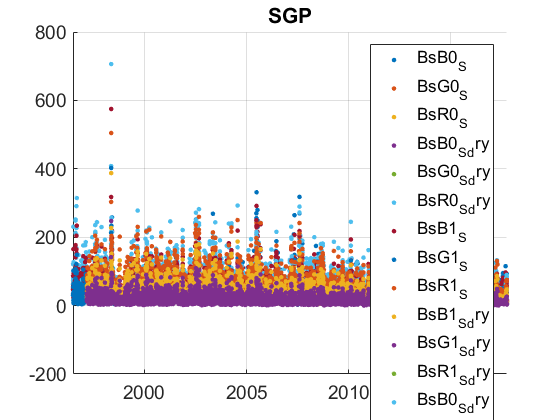

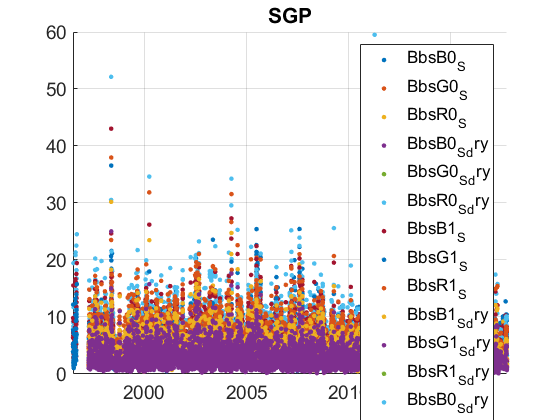

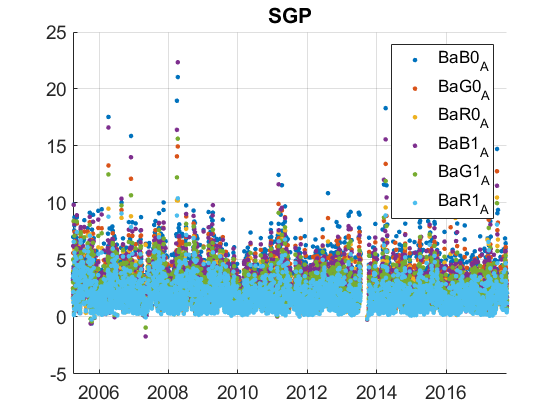

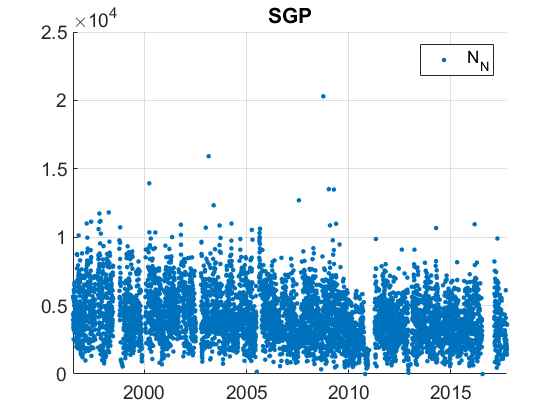

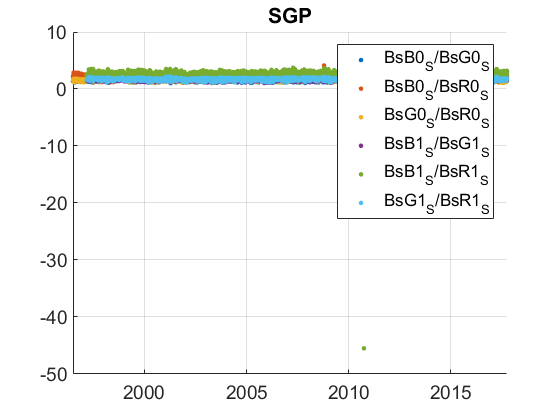

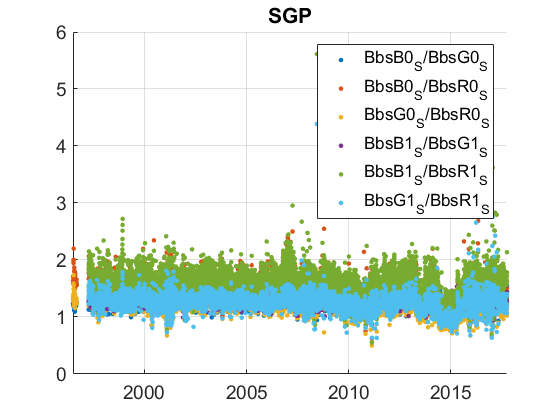

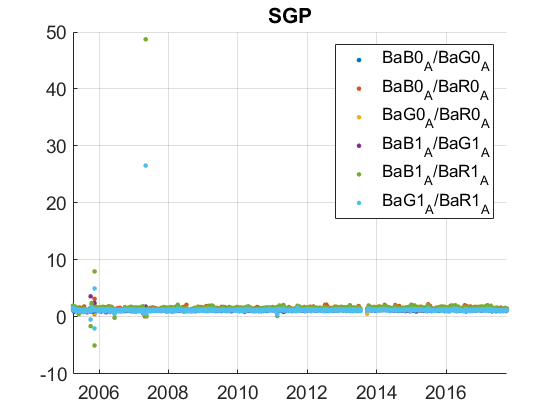

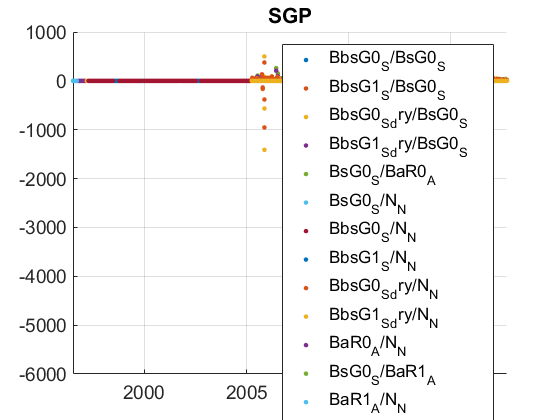

plotFigControl(SGP_rd,SGP_st.name);

% 2 size cut, ok
% sc: ok, no negatives, no clear seasonal cycle

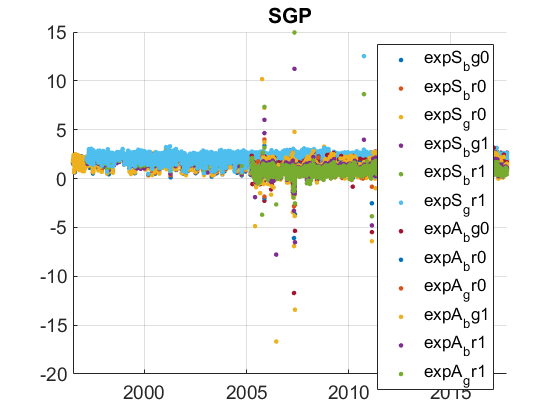

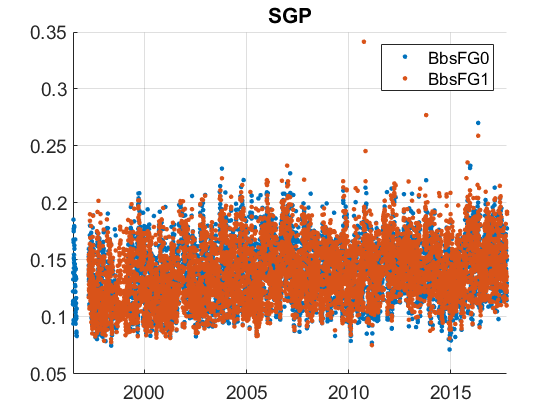

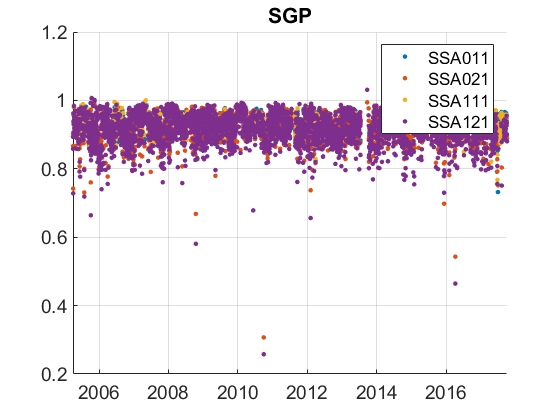

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
SGP_cal=compute_exp_SSA(SGP_rd,lambdaSC, lambdaAE);
plotFigControl_cal(SGP_cal, SGP_st.name);

%Questions:
%problems:

%humidity: what is the difference between the U0_S and the Uu0_S ? the Uu seems to be less homogeneous.


% sc: the scat seems ok for the whole time period
% the ratio (and exponent) of sc is strange for BR and GR with ruptures un June 2013, July 2014 and May 2015: what happened?
%the ratio of Bsc with blue is too high in January 2007, and with red if too low from May-Sept 2013 and from May 2014 to May 2015


%abs: should the very low ratio and exponents in April 2007 be deleted ?
%SSA and BbsF seem ok


SGP_tr=SGP_rd;
SGP_tr.y=year(SGP_tr.Time);
% begin at the beginning of a year:sc:  1997 , abs: 2006
%end: 2017 (October)
P=timerange('1997-01-01','2018-01-01');
SGP_tr=SGP_tr(P,:);
%U0_S and U1_S > 100 to invalidate (a lot at 524)
% not use Uu

% %U max higher in 2005-2012 and 2016-1017 --> trend in U + trend dry
names=fieldnames(SGP_tr);
c= startsWith(names,["T1";"T0";"T_";"Tu";"P_";"P1_";"P0_";"N";"Uu"]);
N=names(c);
for i=1:length(N)
    SGP_tr.(N{i})=[];
end

%Ba PM10: 2007-2017 if 2017 complete
pp1=timerange('1996-01-01','2006-01-01');
c=startsWith(names,["Ba0"]);
N=names(c);
for i=1:length(N)
    SGP_tr.(N{i})(pp1)=NaN;
end

%Bbs  and Bs PM1: 1998-2017 if 2017 complete
pp2=timerange('1996-01-01','1998-01-01');
c=startsWith(names,["Bbs";"BsB1";"BsG1";"BsR1"]);
N=names(c);
for i=1:length(N)
    SGP_tr.(N{i})(pp2)=NaN;
end

%U>100 to invalidate
SGP_tr.U0_S(SGP_tr.U0_S>100)=NaN;
%compute new values
SGP_cal2=compute_exp_SSA(SGP_tr,lambdaSC, lambdaAE);
SGP_tr=outerjoin(SGP_tr, SGP_cal2);
SGP_tr.SSA0G=SGP_tr.BsG0_S./(SGP_tr.BsG0_S+SGP_tr.BaG0_A);
SGP_tr.SSA1G=SGP_tr.BsG1_S./(SGP_tr.BsG1_S+SGP_tr.BaG1_A);
SGP_tr.SSA0G_dry=SGP_tr.BsG0_S_dry./(SGP_tr.BsG0_S_dry+SGP_tr.BaG0_A);
SGP_tr.SSA1G_dry=SGP_tr.BsG1_S_dry./(SGP_tr.BsG1_S_dry+SGP_tr.BaG1_A);
SGP_tr.expS_bg0_dry=real(-log(SGP_tr.BsB0_S_dry./SGP_tr.BsG0_S_dry)/log(lambdaSC(1)/lambdaSC(2)));
SGP_tr.expS_bg1_dry=real(-log(SGP_tr.BsB1_S_dry./SGP_tr.BsG1_S_dry)/log(lambdaSC(1)/lambdaSC(2)));
SGP_tr.BbsFG0_dry=SGP_tr.BbsG0_S_dry./SGP_tr.BsG0_S_dry;
SGP_tr.BbsFG1_dry=SGP_tr.BbsG1_S_dry./SGP_tr.BsG1_S_dry;

%compute trend only on G
SGP_tr.BsB0_S=[];
SGP_tr.BsR0_S=[];
SGP_tr.BbsB0_S=[];
SGP_tr.BbsR0_S=[];
SGP_tr.BsB1_S=[];
SGP_tr.BsR1_S=[];
SGP_tr.BbsB1_S=[];
SGP_tr.BbsR1_S=[];
SGP_tr.BsB0_S_dry=[];
SGP_tr.BsR0_S_dry=[];
SGP_tr.BbsB0_S_dry=[];
SGP_tr.BbsR0_S_dry=[];
SGP_tr.BsB1_S_dry=[];
SGP_tr.BsR1_S_dry=[];
SGP_tr.BbsB1_S_dry=[];
SGP_tr.BbsR1_S_dry=[];
%Abs: 2006-2017 if complete
SGP_tr.BaB0_A=[];
SGP_tr.BaR0_A=[];
SGP_tr.BaB1_A=[];
SGP_tr.BaR1_A=[];

SGP_tr.expS_br0=[];
SGP_tr.expS_br1=[];
SGP_tr.expS_gr0=[];
SGP_tr.expS_gr1=[];

SGP_tr.expA_br0=[];
SGP_tr.expA_gr0=[];
SGP_tr.expA_br1=[];
SGP_tr.expA_gr1=[];

SGP_tr.SSA011=[];
SGP_tr.SSA021=[];
SGP_tr.SSA111=[];
SGP_tr.SSA121=[];
P1=timerange('2012-05-21','2013-04-22');
P2=timerange('2014-05-29','2015-04-27');
P3=timerange('2006-09-09','2007-05-20');
%expS: to invalidate:  May 21, 2012 - April 22, 2013 and May 29, 2014 - April 27, 2015 and Sept 9 2006-May 20 2007
names=fieldnames(SGP_tr);
c=startsWith(names,'expS');
N=names(c);
for i=1:length(N)
      SGP_tr.(N{i})(P1)=NaN;
      SGP_tr.(N{i})(P2)=NaN;
      SGP_tr.(N{i})(P3)=NaN;
end
%BbsF: to invalidate  May 29, 2014 - April 27, 2015 and Sept 9 2006-May 20 2007
c=startsWith(names,'BbsF');
N=names(c);
for i=1:length(N)
      SGP_tr.(N{i})(P2)=NaN;
      SGP_tr.(N{i})(P3)=NaN;
end
%ExpA: to invalidate 3 April 2007 to 24 Mai 
P4=timerange('2007-04-03','2007-05-23');
SGP_tr.expA_bg0(P4)=NaN;
SGP_tr.expA_bg1(P4)=NaN;
%SSA: ok 2006-2017

SGP_result=all_trend_STN(SGP_tr,SGP_st);
plot_10y_in_two(SGP_result,SGP_st);

SGP_result_D=SGP_result;
%remove Tu trends (were not remove before, script changed but not rerun)
SGP_result_D=SGP_result_D(startsWith(SGP_result_D.parameter,'Tu')==0,:);